ECG Template

load("ECG_template.mat");

fs = 500;  % Sampling frequency = 500 Hz
T = 1/fs;  % T= Sampling period

num_points = size(ECG_template, 2);
time_axis = linspace(0, T * (num_points-1), num_points);  %time axis from the frequency

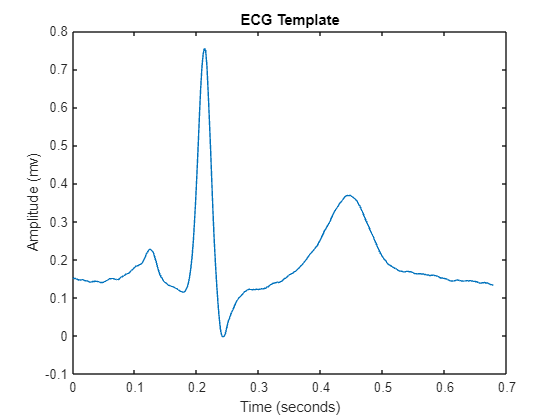

figure;
plot(time_axis, ECG_template);
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('ECG Template');

Noisy ECG

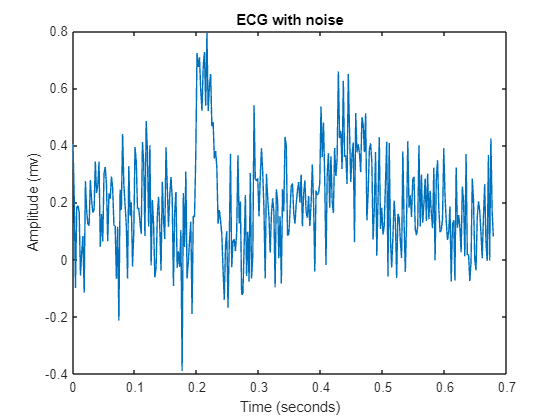

snr = 5; %signal-noise ratio in decible
seed = 10;
nECG = awgn(ECG_template,snr,'measured',seed);

figure;
plot(time_axis, nECG);
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('ECG with noise');

PSD of noisy ECG

Initializing Window Designer....

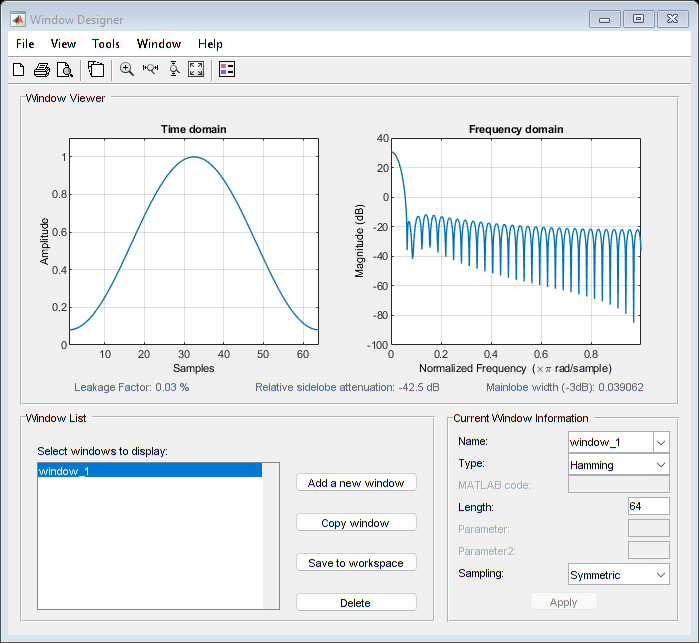

. done. 


nfft = num_points;
[pxx_nECG,f_nECG] = periodogram(nECG,window,nfft,fs);

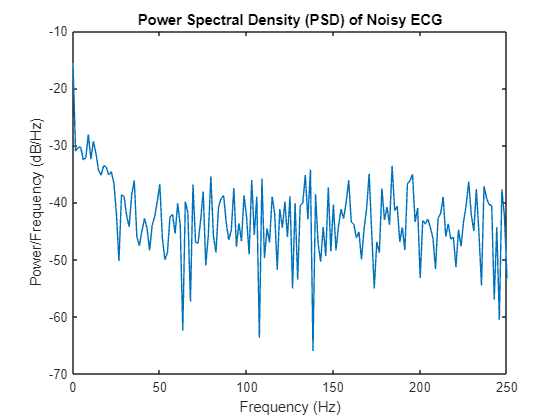


figure;
plot(f_nECG, 10*log10(pxx_nECG)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of Noisy ECG');

MA(3) filter implementation with a customised script

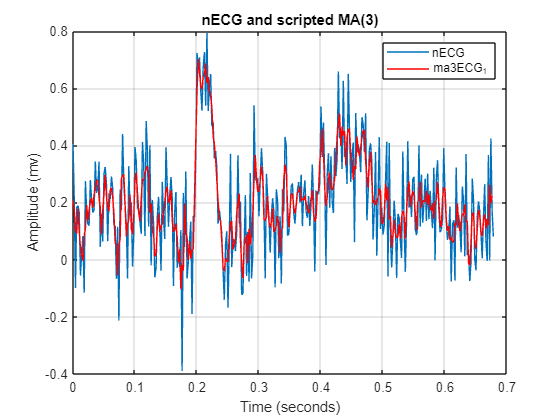

ma3ECG_1 = moving_average_filter(3,nECG);
group_delay = 1;  %derivation of group delay is in the report
compensated_time_axis = time_axis(1:end-group_delay);
ma3ECG_1(1:group_delay) = [];

figure;
plot(time_axis, nECG);
hold on;  
plot(compensated_time_axis, ma3ECG_1, 'r');
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('nECG and scripted MA(3)');
legend('nECG', 'ma3ECG_1');
hold off;
grid on;

Compare PSDs

Initializing Window Designer....

. done. 


[pxx_ma3,f_ma3] = periodogram(ma3ECG_1,window,nfft,fs);

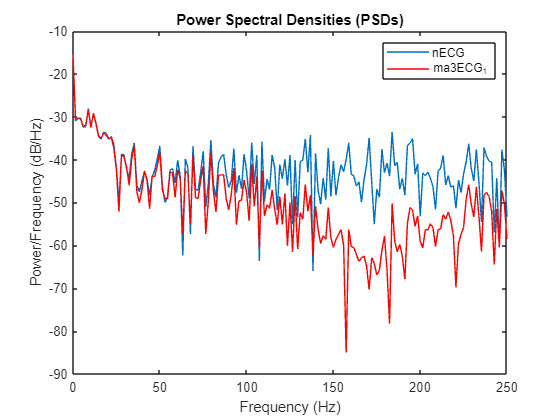

figure;
plot(f_nECG, 10*log10(pxx_nECG));
hold on;
plot(f_ma3, 10*log10(pxx_ma3),'r');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Densities (PSDs)');
legend('nECG', 'ma3ECG_1');
hold off;

MA(3) filter implementation with the MATLAB built-in function

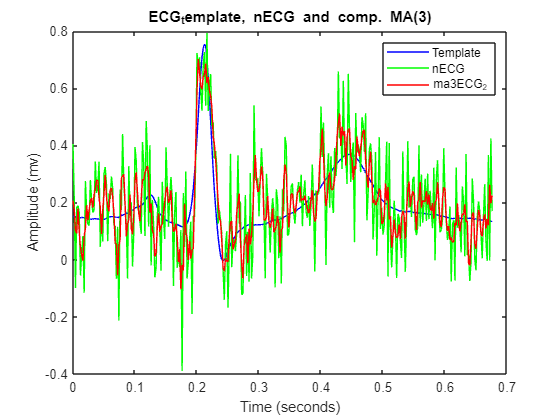

windowSize = 3; 
numerator = (1/windowSize)*ones(1,windowSize);
denominator = 1;

ma3ECG_2 = filter(numerator,denominator,nECG);
delay = mean(grpdelay(numerator, denominator, fs));
compensated_time_axis = time_axis(1:end-delay);
ma3ECG_2_copy = ma3ECG_2;
ma3ECG_2(1:delay) = [];


figure;
plot(compensated_time_axis, ECG_template(1:end-delay), 'b');
hold on;  
plot(compensated_time_axis, nECG(1:end-delay), 'g');
hold on;
plot(compensated_time_axis, ma3ECG_2, 'r' )
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('ECG_template, nECG and comp. MA(3)');
legend('Template','nECG', 'ma3ECG_2');
hold off;

FVT tool

fvtool(numerator,denominator);

MA(10) filter implementation with the MATLAB built-in function

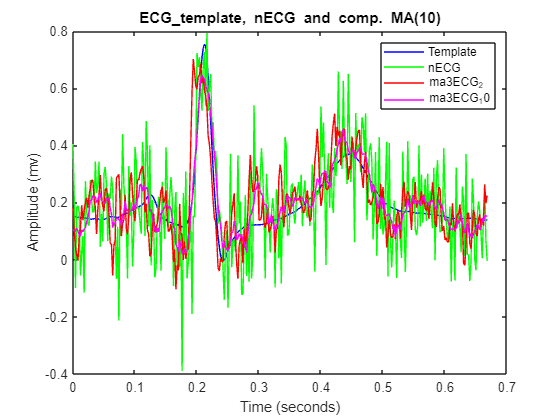

windowSize = 10; 
numerator = (1/windowSize)*ones(1,windowSize);
denominator = 1;
fvtool(numerator,denominator);

ma10ECG = filter(numerator,denominator,nECG);
delay = round(mean(grpdelay(numerator, denominator, fs)));
ma10ECG_copy = ma10ECG;

compensated_time_axis = time_axis(1:end-delay);
ma10ECG(1:delay) = [];
ma3ECG_2_copy(1:delay) = [];


figure;
plot(compensated_time_axis, ECG_template(1:end-delay), 'b');
hold on;  
plot(compensated_time_axis, nECG(1:end-delay), 'g');
hold on;
plot(compensated_time_axis, ma3ECG_2_copy, 'r' )
hold on;
plot(compensated_time_axis, ma10ECG, 'm' )
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('ECG\_template, nECG and comp. MA(10)');
legend('Template','nECG', 'ma3ECG_2', 'ma3ECG_10');
hold off;

Optimum MA(N) filter order

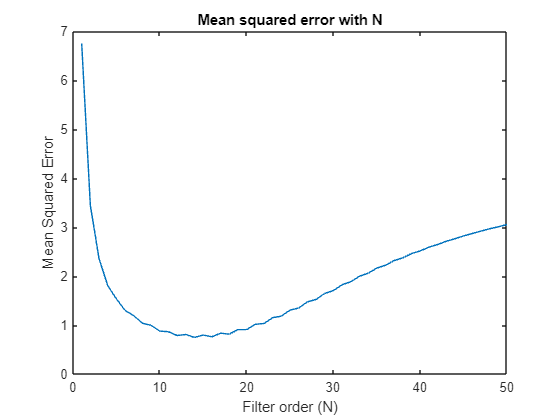

N_values = [];
MSE_values = [];
minimum_error = inf;
minimum_error_when_N = 0;
for windowSize = 1:50
    numerator = (1/windowSize)*ones(1,windowSize);
    denominator = 1;

    filtered_signal = filter(numerator,denominator,nECG);
    delay = round(mean(grpdelay(numerator, denominator, fs)));
    filtered_signal(1:delay) = [];
    MSE = mean_squared_error(ECG_template(1:end-delay),filtered_signal);
    
    N_values = [N_values, windowSize];
    MSE_values = [MSE_values, MSE];

    if MSE<minimum_error 
        minimum_error = MSE;
        minimum_error_when_N = windowSize;
    end
end

figure;
plot(N_values,MSE_values);
xlabel('Filter order (N)');
ylabel('Mean Squared Error');
title('Mean squared error with N');

fprintf('Minimum Error = %0.3f\n', minimum_error);

Minimum Error = 0.746


fprintf('At Minimum Error, N= %.0f\n', minimum_error_when_N);

At Minimum Error, N= 14
